# NACA airfoil wing model

Finite element model from the following reference:

Jain, S., Tiso, P., Rutzmoser, J. B., & Rixen, D. J. (2017). A quadratic manifold for model order reduction of nonlinear structural dynamics. *Computers & Structures*, *188*, 80–94. [https://doi.org/10.1016/J.COMPSTRUC.2017.04.005](https://doi.org/10.1016/J.COMPSTRUC.2017.04.005)

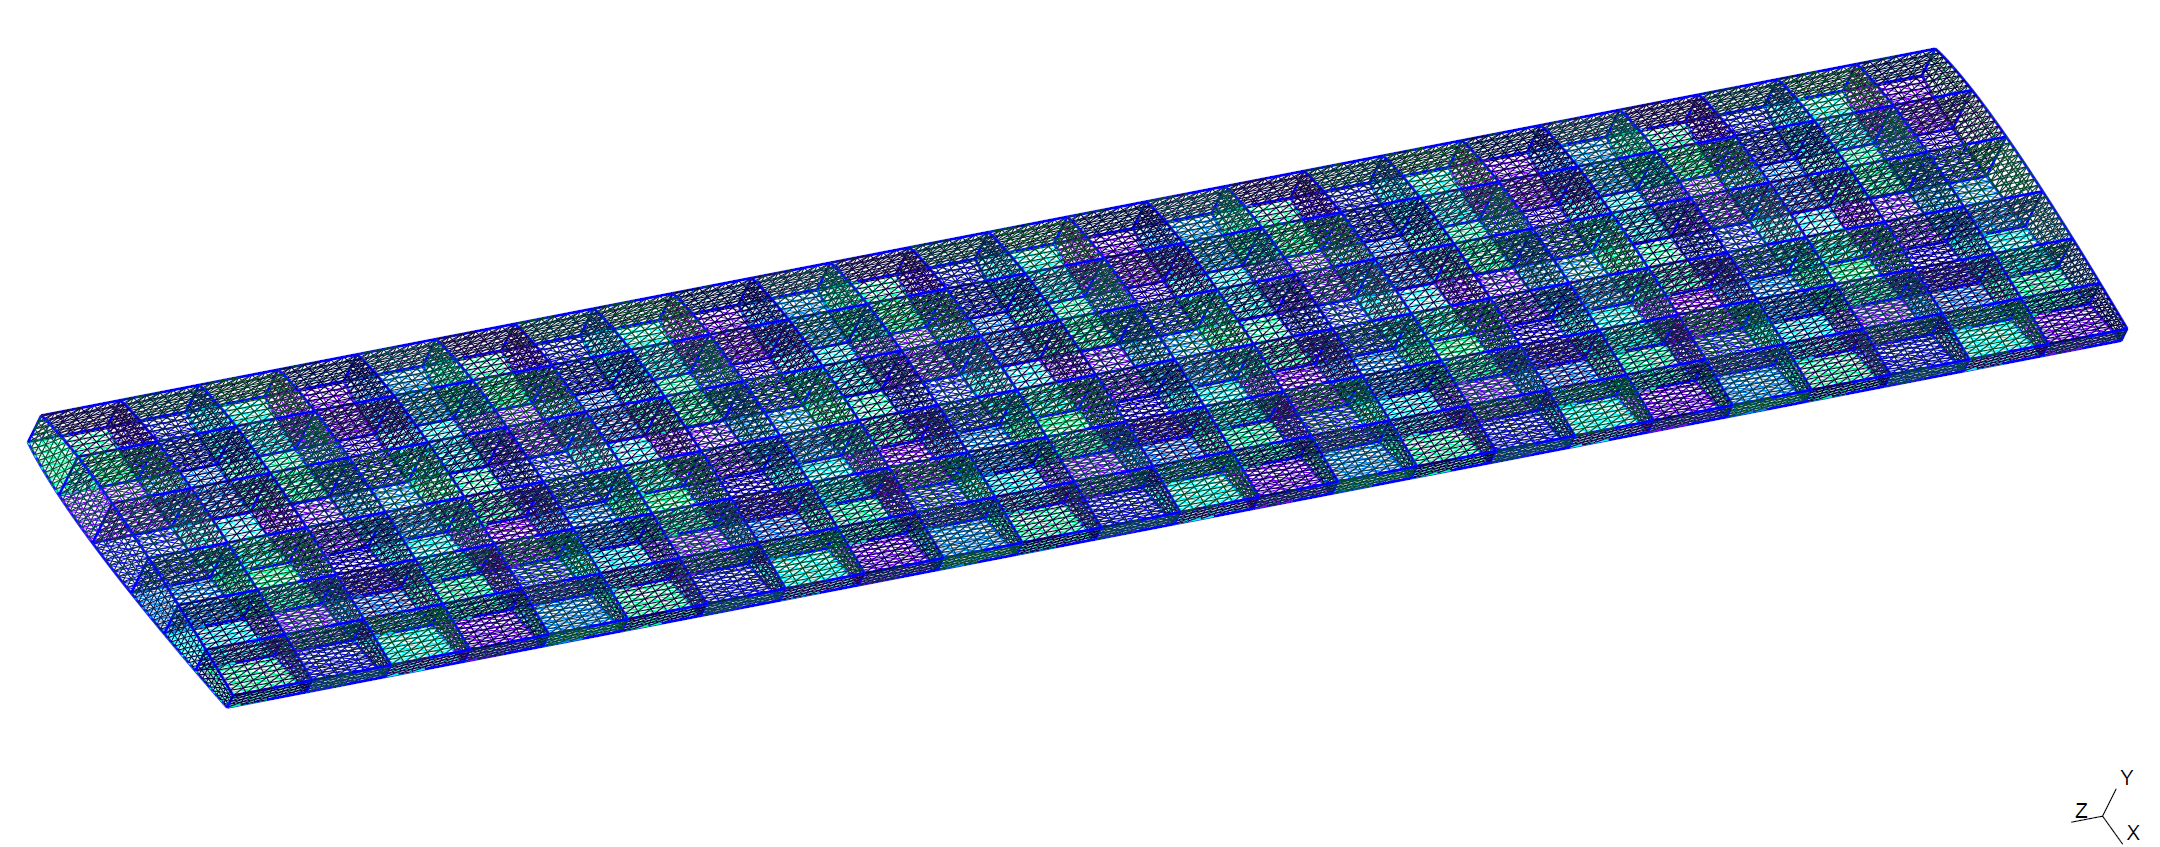

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

**system parameters**

epsilon = 1;

## generate model

[M,C,K,fnl,f_0,outdof] = build_model();

'build_model' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/jalora/SoftRobot_SSMLearn/ext/SSMTool/examples/vonKarmanShell
    /Users/jalora/SoftRobot_SSMLearn/ext/SSMTool/examples/vonKarmanPlate
    /Users/jalora/nlmr/matlab/ext/SSMTool/examples/NACAWing

Change the MATLAB current folder or add its folder to the MATLAB path.

n = length(M);
disp(['Number of degrees of freedom = ' num2str(n)])
disp(['Phase space dimensionality = ' num2str(2*n)])

## Dynamical system setup 

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$.

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',30,'Nmax',30,'notation','multiindex')
% set(DS.Options,'Emax',5,'Nmax',10,'notation','tensor')

We assume periodic forcing of the form


$$\mathbf{f}^{ext}(\phi) = \mathbf{f}_0\cos(\phi)=\frac{\mathbf{f}_0}{2}e^{i\phi} + \frac{\mathbf{f}_0}{2}e^{-i\phi}  $$


Fourier coefficients of Forcing

kappas = [-1; 1];
coeffs = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas,epsilon);

## Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();
plot_eigenvalues_in_complex_plane(D)

**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,2]; 
S.choose_E(masterModes);

## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 3; % Approximation order

setup options

set(S.Options, 'reltol', 1,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',false)
set(S.FRCOptions, 'nt', 2^7, 'nRho', 200, 'nPar', 200, 'nPsi', 100, 'rhoScale', 2 )
% set(S.FRCOptions, 'method','level set')
set(S.FRCOptions, 'method','continuation ep', 'z0', 1e-4*[1; 1])
set(S.FRCOptions, 'outdof',outdof)

choose frequency range around the first natural frequency

omega0 = imag(S.E.spectrum(1));
omegaRange = omega0*[0.9 1.1];

extract forced response curve

FRC = S.extract_FRC('freq',omegaRange,order);
figFRC = gcf;